# Relazione 5 analisi 2

## Dati

Rt1 = [10.16 7.33 5.20 1.98 0.22]; % in kOhm
Rt2 = [0.18 2.79 4.96 8.15 10.13]; % in kOhm
Ra = ones(1,5).*1; % in kOhm
Rt = Rt1 + Rt2

Rt =    10.3400   10.1200   10.1600   10.1300   10.3500


## Misure e calcoli

dc_meas = [99.42 74.14 56.86 26.60 9.06] % in percentuale

dc_meas =    99.4200   74.1400   56.8600   26.6000    9.0600


dc_calc =  (Rt1./Rt).*100; % in percentuale
dc_prec = (Ra+Rt1)./(Ra+Rt).*100; % in percentuale

## Grafico

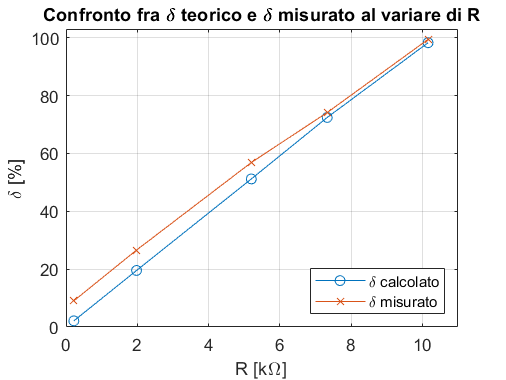

figure
plot(Rt1,dc_calc,'-o')
hold on
grid on
plot(Rt1,dc_meas,'-x')
title('Confronto fra \delta teorico e \delta misurato al variare di R')
xlabel('R [k\Omega]'); ylabel('\delta [%]')
ylim([0 103]); xlim([0 11]);
legend('\delta calcolato','\delta misurato','Location','southeast')
% Cambiare con il percorso in cui si ha la cartella immagini della relazione
saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S1\LabElettronica\Relazioni-Lab-Elettronica\Relazione 5\TexFiles\immagini\graficomis4.png');

## Grafico preciso

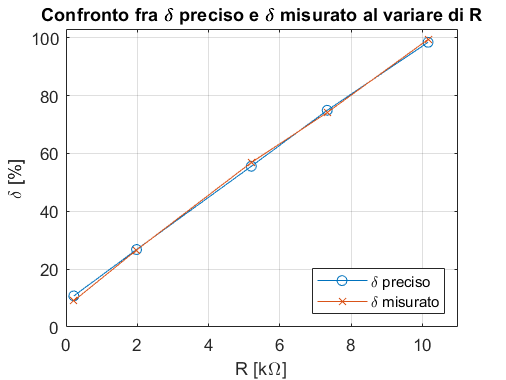

figure
plot(Rt1,dc_prec,'-o')
hold on
grid on
plot(Rt1,dc_meas,'-x')
title('Confronto fra \delta preciso e \delta misurato al variare di R')
xlabel('R [k\Omega]'); ylabel('\delta [%]')
ylim([0 103]); xlim([0 11]);
legend('\delta preciso','\delta misurato','Location','southeast')
% Cambiare con il percorso in cui si ha la cartella immagini della relazione
saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S1\LabElettronica\Relazioni-Lab-Elettronica\Relazione 5\TexFiles\immagini\graficomis4_prec.png');